# 適応モデル予測制御によるカート型倒立振子の倒立制御

本例題では、カート型倒立振子の倒立制御を適応モデル予測制御によって行う。

カート型倒立振子は状態量にカート位置と速度、倒立角とその角速度の4状態量を持つ非線形システムであり、

操作量はカートに加えるForce[N]である。

clc,clear

mdl = 'pendcartMPC';
open_system(mdl)

% Initial value
x0 = zeros(4,1);
u0 = zeros(1,1);

MPC制御パラメーターを設定する

% Control params
Ts = 0.01;                      %サンプリング時間
params.Q = diag([1,2]);         %出力の重み
params.R = 1;                   %入力の重み
params.PredictiveHorizon = 60;  %予測ホライズン
params.Controlhorizon = 2;      %制御ホライズン
params.MV_max = 100;            %入力制約
params.MV_min = -100;
params.dMV_max = 10;            %入力変化率制約
params.dMV_min = -10;
params.MV_scalefactor = 100;    %入力のスケールゲイン
params.SolverType = 2;          %ソルバータイプ2：Interiror Point Method
params.IterationMax = 100;      %ソルバーの最大イテレーション回数

AMPCにて必要となるバスオブジェクトは専用のAPIを使用してワークスペースに作成できる。

% Create sysBus object
n = 4;          %状態量の次数
m = 1;          %操作量の次数
l = 2;          %出力の次数
nd = 0;         %外乱の次数
sysBus = createSysBusObject(n,m,nd,l);

状態推定のために拡張カルマンフィルターを設計する

Bv = eye(n);         %システムノイズにかかる入力ベクトル
Q = diag([1,1,1,1]);    %システムノイズの重み
R = diag([1,1]);        %
xhat0 = x0;
P0 = eye(n);

シミュレーションを実行する。

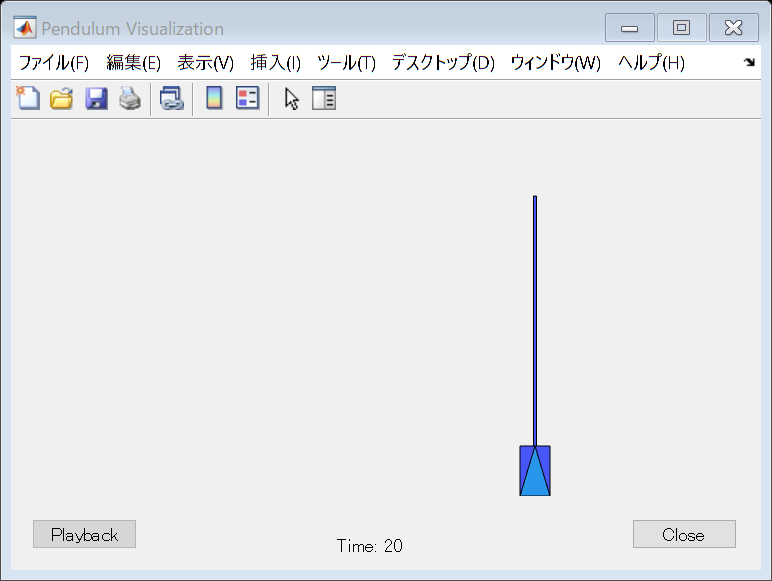

tic
sim(mdl)

toc

経過時間は 87.636582 秒です。
